%wind导入历史行情序列
w = windmatlab;
begintime='20030725';     %股票上市日
endtime='20201014';       %可转债上市前一日
[w_wsd_data,w_wsd_codes,w_wsd_fields,w_wsd_times,w_wsd_errorid] = w.wsd('600029.SH','close',begintime,endtime,'Priceadj=B','tradingcalendar=SSE','Days=Trading')  %获取收盘价（后复权）

w_wsd_data =     3.8800
    3.9200
    3.9200
    4.0800
    4.0500
    4.0200
    4.0300
    4.0100
    3.9800
    4.0000


w_wsd_codes = 1×1 cell array
    {'600029.SH'}


w_wsd_fields = 1×1 cell array
    {'CLOSE'}


w_wsd_times =       731787
      731790
      731791
      731792
      731793
      731794
      731797
      731798
      731799
      731800


w_wsd_errorid = 0

SA = [w_wsd_times,w_wsd_data]

SA = 	1.0e+05 *

    7.3179    0.0000
    7.3179    0.0000
    7.3179    0.0000
    7.3179    0.0000
    7.3179    0.0000
    7.3179    0.0000
    7.3180    0.0000
    7.3180    0.0000
    7.3180    0.0000
    7.3180    0.0000


open SA
clearvars -except SA

%变换数据格式
SA = rmmissing(SA);
time = datetime(SA(:,1),'ConvertFrom','datenum');
prices = SA(:,2);
T = timetable(time,prices);
clearvars -except SA prices time T

econometricModeler

%模型模拟
md1 = GARCH_LogReturns

md1 =   garch with properties:

     Description: "GARCH(1,1) Conditional Variance Model (t Distribution)"
    Distribution: Name = "t", DoF = 4.77437
               P: 1
               Q: 1
        Constant: 5.61913e-06
           GARCH: {0.917436} at lag [1]
            ARCH: {0.0825641} at lag [1]
          Offset: 0

V0 = infer(md1,LogReturns);
[V,Y] = simulate(md1,252,'NumPaths',10000,'E0',LogReturns,'V0',V0)

V =     0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    0.0005    0.0004    0.0004    0.0008    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0004    0.0004    0.0004    0.0005    0.0004    0.0004    0.0004    0.0005    0.0005    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0004    0.0004    0.0004    0

Y =    -0.0253   -0.0027   -0.0084    0.0697    0.0018    0.0087    0.0066   -0.0019   -0.0193    0.0321    0.0064   -0.0107   -0.0027    0.0203    0.0042    0.0039   -0.0056   -0.0240   -0.0166   -0.0142    0.0012    0.0045   -0.0038    0.0119   -0.0084    0.0030   -0.0142   -0.0147   -0.0034    0.0164    0.0047    0.0050   -0.0098   -0.0126    0.0085    0.0110   -0.0221   -0.0278    0.0150   -0.0004   -0.0048    0.0060   -0.0024    0.0056    0.0048   -0.0331    0.0003   -0.0005    0.0080    0.0044
    0.0121   -0.0132   -0.0239   -0.0026   -0.0050    0.0192   -0.0045   -0.0208    0.0075    0.0098    0.0455    0.0159    0.0133    0.0145   -0.0051   -0.0365    0.0111    0.0029    0.0265    0.0159    0.0096   -0.0067    0.0100   -0.0044    0.0035   -0.0009    0.0056    0.0423   -0.0024   -0.0060    0.0233   -0.0099   -0.0007   -0.0161    0.0064    0.0063    0.0086   -0.0000    0.0086   -0.0065   -0.0298   -0.0299    0.0119    0.0545    0.0150   -0.0142    0.0055   -0.0143    0.0153    0

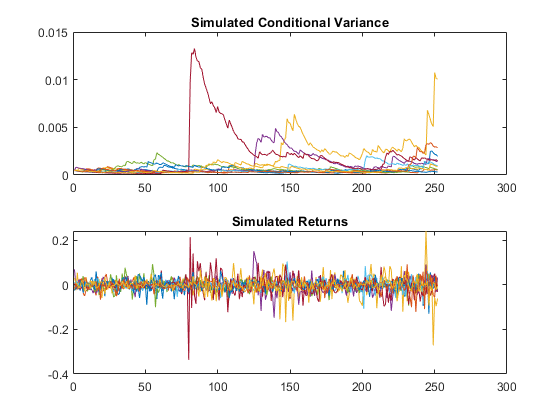

%画出10个路径上的模拟值
figure
subplot(2,1,1)
plot(V(:,1:10))
title('Simulated Conditional Variance')
subplot(2,1,2)
plot(Y(:,1:10))
title('Simulated Returns')

%计算预测波动率和历史波动率
tradingDays = 252;
Fvol = mean(std(Y))*sqrt(tradingDays);
Hvol1Y = std(LogReturns(end-251:end,:))*sqrt(tradingDays);
Hvol5Y = std(LogReturns(2:end,:))*sqrt(tradingDays);
disp(['Forecasted 1-year volatility = ' num2str(Fvol*100,4) '%'])

Forecasted 1-year volatility = 45.01%


disp(['Historical 1-year volatility = ' num2str(Hvol1Y*100,4) '%'])

Historical 1-year volatility = 31.69%


disp(['Historical 5-year volatility = ' num2str(Hvol5Y*100,4) '%'])

Historical 5-year volatility = 45.65%


%获取CB发行后行情序列
w = windmatlab;
begintime = '20191015';
endtime = today;
[w_wsd_data,w_wsd_codes,w_wsd_fields,w_wsd_times,w_wsd_errorid] = w.wsd('600029.SH','close',begintime,endtime,'Priceadj=B','tradingcalendar=SSE','Days=Trading')  %获取收盘价（后复权）

w_wsd_data =    11.7697
   11.6676
   11.7697
   11.4805
   11.3615
   11.3615
   11.2424
   11.2424
   11.2084
   11.4975


w_wsd_codes = 1×1 cell array
    {'600029.SH'}


w_wsd_fields = 1×1 cell array
    {'CLOSE'}


w_wsd_times =       737713
      737714
      737715
      737716
      737719
      737720
      737721
      737722
      737723
      737726


w_wsd_errorid = 0

SA_I=[w_wsd_times,w_wsd_data]

SA_I = 	1.0e+05 *

    7.3771    0.0001
    7.3771    0.0001
    7.3772    0.0001
    7.3772    0.0001
    7.3772    0.0001
    7.3772    0.0001
    7.3772    0.0001
    7.3772    0.0001
    7.3772    0.0001
    7.3773    0.0001


open SA_I
clearvars -except SA_I

%变换数据格式
SA_I = rmmissing(SA_I);
time = datetime(SA_I(:,1),'ConvertFrom','datenum');
prices = SA_I(:,2);
T_I = timetable(time,prices);
clearvars -except SA_I prices time T_I

%计算真实波动率
tradingDays = 252;
Hvol1Y = std(LogReturns(end-251:end,:))*sqrt(tradingDays);

Reference to a cleared variable LogReturns.

disp(['Historical 1-year volatility = ' num2str(Hvol1Y*100,4) '%'])